## Granger Causality walkthrough

### This live script demonstrates some of the steps needed to apply Granger Causality, in the time domain, based on autoregression analysis. Granger Causality is a measure of directed connectivity.  

clear
% first load example data, make sure the data are in the current directory,
% or in the path
load('ECOG.mat') % loads channels of ECOG (implanted electrodes), 
% 3 channels in inferior temporal lobe;  3 channels posterior temporal
size(data)

ans =            6       51001


SampRate = 500; 

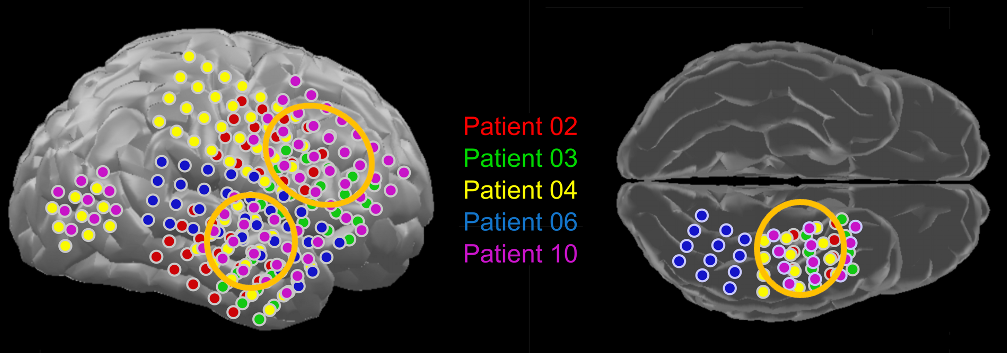

First, a brief illustration of auto-regression: we predict future data points using a regression model that uses past data points as predictors, and this model is shifted across the time series. to imagine how this works, let's use the data we have and predict future points by past points in a simple scatter plot

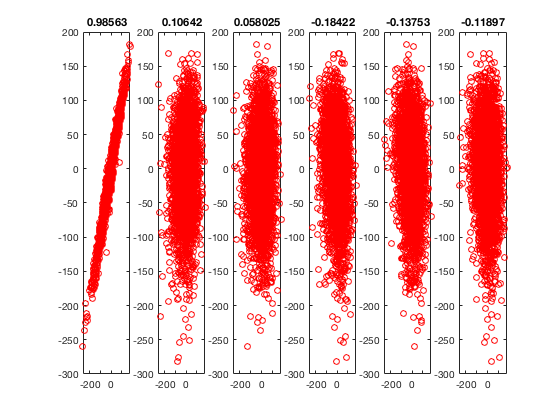


fig=1; 
for lag = 1:25:140 
subplot(1,6,fig), hp = plot(data(4, 1:10:end-lag), data(4, lag+1:10:end), 'ro'); hl = lsline(hp);
title(num2str(corr(data(4, 1:end-lag)', data(4, lag+1:end)')))
fig = fig+1;   
end

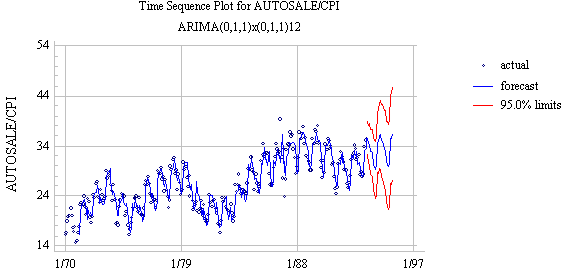

## A typical Granger causality analysis - in the time domain

The following wo steps are interactive and iterative, you may want to change many paraneters and see what they do 

warning('off')
[bic,aic] = aks_find_model_order(data,2,19)

VAR order 2, bic1 = 16.3814, AIC = 16.3689
VAR order 3, bic1 = 11.662, AIC = 11.6433
VAR order 4, bic1 = 5.0532, AIC = 5.0283
VAR order 5, bic1 = -1.9386, AIC = -1.9698
VAR order 6, bic1 = -8.0524, AIC = -8.0899
VAR order 7, bic1 = -8.6253, AIC = -8.669
VAR order 8, bic1 = -8.512, AIC = -8.562
VAR order 9, bic1 = -9.8622, AIC = -9.9183
VAR order 10, bic1 = -9.9121, AIC = -9.9745
VAR order 11, bic1 = -10.5038, AIC = -10.5724
VAR order 12, bic1 = -9.9838, AIC = -10.0586
VAR order 13, bic1 = -8.9703, AIC = -9.0514
VAR order 14, bic1 = -12.1098, AIC = -12.1972
VAR order 15, bic1 = -11.4115, AIC = -11.5051
VAR order 16, bic1 = -10.1115, AIC = -10.2113
VAR order 17, bic1 = -11.1922, AIC = -11.2982
VAR order 18, bic1 = -11.5185, AIC = -11.6308
VAR order 19, bic1 = -10.8599, AIC = -10.9784


bic = 14

aic = 14

 Figure out if data are covariance stationary = must have NO "unit root"  A time series has a unit (one) root if 1 is a root (solution) of the       

 autoregressive equation that describes the time series. Such a process is non-stationary. 

  We test for stationarity with the Augmented Dickey-Fuller test

modelorder = 14

modelorder = 14

uroot = aks_check_covariance_stationarity(data, modelorder)

uroot =      1
     1
     1
     1
     1
     1


It is typical for brain data to be non-stationary, so we often need to do a transformation tha keeps the dynamics intact but creates stationarity

data_z = z_norm(data); % z-transform
uroot = aks_check_covariance_stationarity(data_z, modelorder)

uroot =      1
     1
     1
     1
     1
     1



data_white = data_z+rand(size(data_z)); % whitening (adding white noise)
uroot = aks_check_covariance_stationarity(data_white, modelorder)

uroot =      0
     0
     0
     0
     0
     0


Now do the actual granger causality

[res,RSS1] = aks_granger_regress_as(data_white,modelorder);

res.gc % p-values

ans =        NaN         0         0         0         0         0
         0       NaN    0.0000         0         0    0.0100
         0    0.0000       NaN    0.0000    0.0026    0.0276
         0         0    0.0000       NaN    0.0000         0
         0         0    0.0000         0       NaN         0
         0         0    0.0001         0         0       NaN



res.fs % F-values ('significance")

ans =          0  100.6519   13.6382   35.3267   26.6256    8.8725
  106.3959         0    4.3005   12.3119    8.1797    2.0814
   11.4672    5.5420         0    5.6277    2.3782    1.8415
   46.6594   20.1417    6.7033         0    6.8340   12.1913
   67.1404   23.3432    7.2060   20.6472         0  114.2512
   12.9058    8.5866    2.9696   25.8576   47.3663         0



log(res.fs)  % magnitude of the connectivity

ans =       -Inf    4.6117    2.6129    3.5646    3.2819    2.1830
    4.6672      -Inf    1.4587    2.5106    2.1017    0.7330
    2.4395    1.7124      -Inf    1.7277    0.8663    0.6106
    3.8429    3.0028    1.9026      -Inf    1.9219    2.5007
    4.2068    3.1503    1.9749    3.0276      -Inf    4.7384
    2.5577    2.1502    1.0884    3.2526    3.8579      -Inf


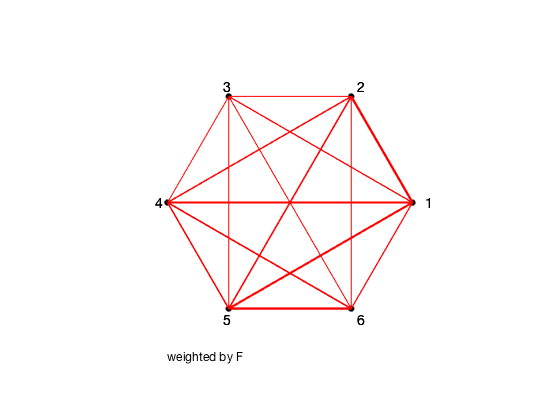

[GC,FS] = aks_findsignificance(res.gc,res.fs,0.05,1); % threshold results by "significance"

% plot results: 
figure, 
aks_plotcausality(res.fs,2);

% extract more gglobal meausres of causal density and flow

[cd,cdw] = aks_causaldensity(GC,FS)

[flow] = aks_causalflow(GC,FS);

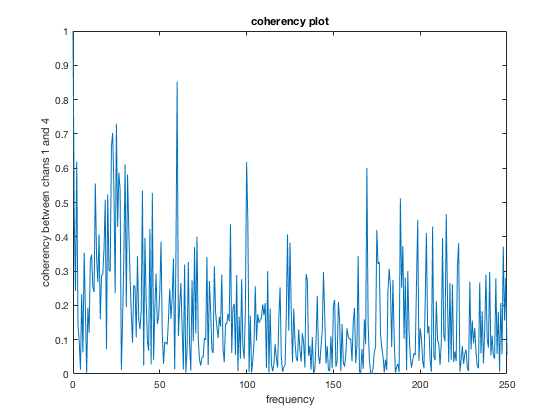

% compare with coherence
[Cxy, F] = mscohere(data_white(1,:)',data_white(4,:)', [], 1, 700, 500);
figure, plot(F,Cxy), xlabel('frequency'), ylabel ('coherency between chans 1 and 4'), 
title ('coherency plot')